## **Day3 データの解析**

**★Ex.01~04までを埋めましょう。**

**★筋電図の意味を考えてみましょう。**

**筋電はある一つの筋群で発生する電位差を捉えたものです。**

**★時間的解析**

**・動くまでの反射などを計測する場合は、トリガーを計測してそこから運動開始時までの時間を用いて評価を行う。**

**・体勢の立て直しなどは運動開始から運動終了までの時間を評価する。**

**・時間的解析を行う場合は、最初しばらくは安静にしてbaselineを計測し、baseline± 2 or 3 ×SDを超えた地点を筋活動開始、戻ってからを終了とする**

**★周波数解析**

筋電の場合は周波数平均もしくは周波数中央値を用いて評価を行う。

-->筋疲労解析

一般的に筋が疲労するに従い周波数が低い方へシフトする。

注意ポイント：

・評価する運動の中に収縮の増減が含まれる場合、平均周波数は増加する 　

　　→運動が複雑な場合、その運動そのものを評価するのではなく、前後で最大等尺性収縮運動を行い、その変化を比較する。

・複数の筋群が協調的に動作に関与する場合、正しいポーズを用いなければ、周辺筋群が代替して運動を行い、疲労を正しく評価できない。

　　→正確な計測条件を設定する（肘を何度に曲げる、椅子に座る　etc.を設定して、ターゲットとなる筋群で正確に測定できるようにしよう）。

**★量的解析**

まず振幅を整流処理 or RMS処理する。

他人同士で比較した時、最大筋力発揮時以外を比較する場合は、最大筋力発揮時の平均振幅を合わせて計測し、正規化する。

筋収縮の強度が変化する場合は、どの箇所の筋肉が一番その運動に影響を与えるかを確認し、運動前後で最大等尺性収縮運動をしてその筋電の変化を計測する。

腕立てなどで、筋が収縮、伸展を繰り返す場合は、相ごとに区切って解析を行う。

**前回保存したemgData.matを読み込んで、表示する**

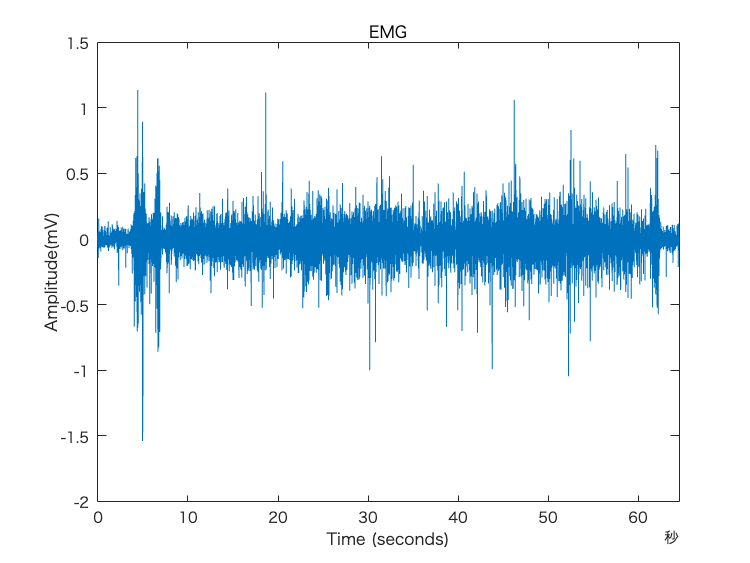


load('emgdata.mat')

t=emgData.time;
emg=emgData.emg;

plot(t,emg)
xlabel('Time (seconds)')
ylabel('Amplitude(mV)')
xlim([0 t(end)])
title('EMG')

FFT解析を行う

fs=1000;

dt=1/fs; 
n=length(emg);
f1 = 0:fs/n:fs/2;

emg_fft=fft(emg);
xdft = emg_fft(1:n/2+1);
psdx = (1/(fs*n)) * abs(xdft).^2;
psdx(2:end-1) = 2*psdx(2:end-1);%



### **★周波数解析**

**周波数解析で、周波数中央値を算出してみましょう。**

%周波数中央値
medFreq = medfreq(emg,fs); %

### **Ex.01: 周波数平均を算出してみましょう。**

%%%%meadFreq = ;

周波数解析の結果を表示してみましょう。

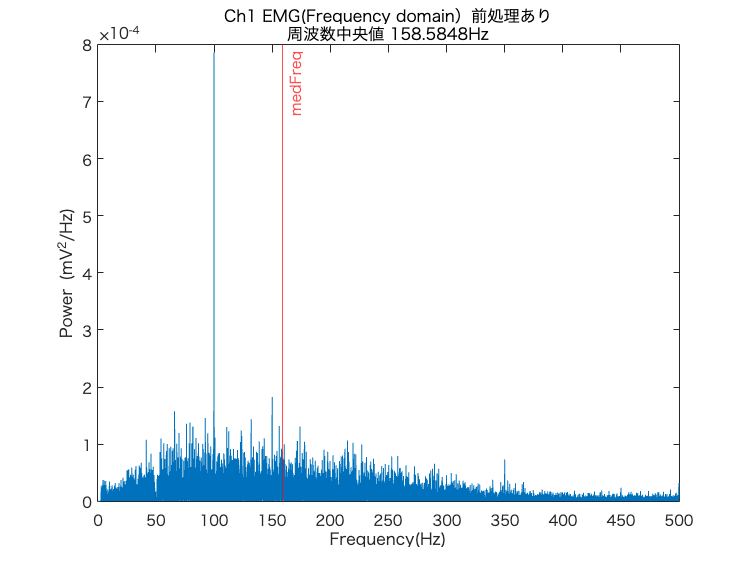

plot(f1, psdx)
xlabel('Frequency(Hz)')
ylabel('Power (V^2/Hz)')
title('Ch1 EMG(Frequency domain）前処理あり')
txt1 = ['周波数中央値 ' num2str(medFreq),'Hz' ];
xline(medFreq,'-r',{'medFreq'});  %%複数記載する場合は、xline([a b c],'-r',{{'aaa','bbb','ccc'});
subtitle(txt1)

**★量的解析**

(50msec区間でRMS処理をして振幅を評価する例)

rmsfreq=50; %50msec
t_rms=t(1:rmsfreq:end);

emg_rms=zeros(n/rmsfreq,1);
d
for i=1:n/rmsfreq
    emg_temp=emg((i-1)*rmsfreq+1:i*rmsfreq);
    emg_rms(i,1)=rms(emg_temp);
end


### **Ex. 02 : 100msecにした際のRMSも算出し、Subplotで50msecと100msecのデータを並べて表示してみましょう**

%%100msec







%%表示



特定の時間区間の平均の振幅を評価してみましょう。

%特定の時間区間の表現
time_idx=[seconds(10)  seconds(20)];%時間の範囲（秒）msecではないので注意
p1=find(t_rms==time_idx(1));
p2=find(t_rms==time_idx(2));




### **Ex.03: 平均振幅と最大振幅を計算してみましょう。(式を埋めてからコメントを解除）**

% meanAmp=      ;%%
% maximumAmp=   ;%%
% text2=['平均振幅は',num2str(meanAmp),'mV; 最大振幅は',num2str(maximumAmp),'mV.'];
% disp(text2) 

最後に、これらの情報をグラフ上に表示して、可視化してみましょう。

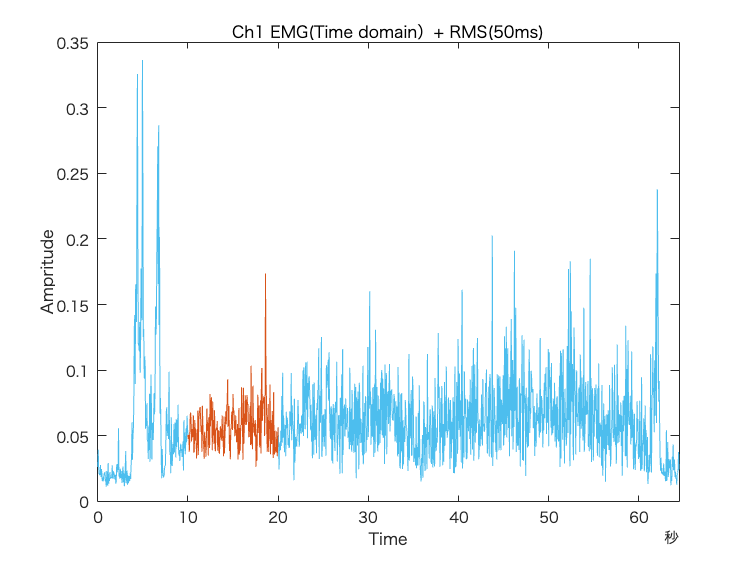


plot(t_rms, emg_rms,"Color",'#4DBEEE');
hold on;
plot(t_rms(p1:p2), emg_rms(p1:p2),"Color",'#D95319');%%一部分だけを色を変えて表示するためのコード。レポートなどで使用する場合に使えます。

% yline(meanAmp,'-r',{'meanAmp'})
% yline(maximumAmp,'-b',{'maximumAmp'})　%%コメントを解除すると図中に最大振幅・平均振幅が表示される
xlabel('Time')
ylabel('Ampritude')
title('Ch1 EMG(Time domain）+ RMS(50ms)')
xlim([0 t_rms(end)])

### **Ex.04: 時間区間を変化させて、平均振幅がどう変化するか解析しましょう。**

### **また、他の人の解析結果と比較して、どういった違いがあるか、その人の背景情報（身長や運動習慣など）も考慮して、考察してみましょう。**

応用：FFTを用いる場合、端点の影響を受けてしまう。避ける為, Hanning窓 などの窓関数を作成し、元信号にかける。もしくはwaveletなどを用いる。